%% Demo: Soft-saturated Lorenz--96 derivative-noise robustness
% Targeted prior-strength/noise robustness ablation for the PhDN manuscript.
%
% This demo reuses the K=10, F=8, kappa=1 soft-saturated Lorenz--96 system,
% the G1/G2/G3 prior definitions, and the PhDN/MLP hyperparameters of the main
% Lorenz--96 identification case.  Within this fixed robustness protocol only
% the derivative-label noise amplitude is varied. Training and validation
% derivatives receive per-coordinate relative Gaussian noise, while the held-
% out ID-test derivatives remain clean. OOD and dynamic rollout are disabled.
%
% Full manuscript robustness run: Ntrain=1000; rho={0,1%,5%,10%}; 3 independent rounds.
% G1/G2/G3 use the finalized general two-restart adaptive-rescue policy.
% Reported methods: PhDN-G1/G2/G3, their collected Stage-0 SR ablations, MLP.

clear; clc;
rng(1);

casemode = 'general';
LorenzDimension = 10;
SaturationKappa = 1;
LorenzForcing = 8;
caseToRun = sprintf('SS_L96_K%d',LorenzDimension);
TrainingSampleList = 1000;
NoiseLevels = [0,0.01,0.05,0.10]; % full derivative-noise robustness sweep
NValidationSamples = 500;
NIDTestSamples = 1000;
NumRounds = 3;
% Keep the same simple round-seed convention as the main Lorenz case.
RoundRandomStateStride = 1;
BaseNoiseSeed = 22001;

% Fixed scrambled-Sobol state samples for all rho and all rounds. Only the
% derivative-noise realization and optimization seed change across rounds.
SamplingMethod = 'scrambled_sobol';
SobolScrambleMethod = 'MatousekAffineOwen';
SobolSkip = 1024;
MaxTrainingSamples = TrainingSampleList;
BaseTrainPoolSeed = 7301;
BaseValidationPoolSeed = 7401;
BaseTestPoolSeed = 7501;
BaseOODPoolSeed = 8501;

projectRoot = pwd;
if ~exist(fullfile(projectRoot,'core'),'dir') || ~exist(fullfile(projectRoot,'tasks'),'dir')
    try
        activeFile = matlab.desktop.editor.getActiveFilename;
        projectRoot = fileparts(activeFile);
    catch
        error('Cannot locate the project root. Set the current folder to the framework root.');
    end
end
addpath(genpath(projectRoot));
addpath(fullfile(projectRoot,'system_identification'),'-begin');
rehash;

caseDefinitionTask = task_soft_saturated_lorenz96( ...
    caseToRun,casemode,LorenzForcing,SaturationKappa);
verify_soft_saturated_lorenz96_case_setup(caseDefinitionTask);

SoftSaturatedLorenz96 mapping verified: x1,...,x10 are cyclic Lorenz--96 states
K=10 | F=8 | kappa=1 | equilibrium max |RHS|=0.000e+00
Alternating joint-OOD static and rollout designs verified.



OutputCaseRoot = fullfile(projectRoot,'outputs', ...
    [caseDefinitionTask.name '_NoiseRobustness']);
OutputSummaryDir = fullfile(OutputCaseRoot,'summary');
if exist(OutputSummaryDir,'dir') ~= 7; mkdir(OutputSummaryDir); end
ResultsFile = fullfile(OutputSummaryDir, ...
    'soft_saturated_lorenz96_noise_robustness_results.mat');

IncludeStage0SRAblationsInComparison = true;
RegeneratePaperFiguresOnly = false;
PaperFigureVisible = true;
PaperFigureExportPDF = true;
RMSEFigureYLimits = []; % []=automatic; optionally set [ymin ymax].
if RegeneratePaperFiguresOnly
    info = regenerate_soft_saturated_lorenz96_noise_robustness_figure( ...
        ResultsFile,OutputSummaryDir,'Visible',PaperFigureVisible, ...
        'ExportPDF',PaperFigureExportPDF, ...
        'IncludeStage0SRAblations',IncludeStage0SRAblationsInComparison, ...
        'YLimits',RMSEFigureYLimits);
    fprintf('\nLorenz--96 noise-robustness figure regenerated from:\n%s\n', ...
        info.sourceResultsFile);
    return;
end
CaseSimulationWallTimer = tic;

%% Stage 0: trivial-output bypass plus native multi-output PySR
% A generic flat SINDy dictionary is accepted only near machine precision.
% All unresolved outputs are searched by PySR with the fine-grained operators
% needed to assemble the soft-saturation law, but without the completed target
% composite feature.
Stage0SingleLayerBypassEnable = true;
Stage0SingleLayerBypassThreshold = 1e-24;

Stage0BasePolyOrder = 2;
Stage0BaseUnaryOperators = {'sqrt'};
Stage0BaseIncludeUnaryOnMonomials = false;
Stage0BaseIncludeOperatorCrossTerms = false;
Stage0BaseIncludeSinCosPair = false;
Stage0BaseMaxLibraryTerms = Inf;
Stage0STLSQThresholdList = [0,1e-8,1e-7,1e-6,1e-5,1e-4,1e-3];
Stage0STLSQMaxIter = 10;
Stage0RidgeLambda = 0;
Stage0WorstOutputWeight = 0.10;

Stage0PythonExe = 'C:\Users\hhy\miniconda3\envs\pysr_sr\python.exe';
Stage0PySRPaperRoot = fullfile(projectRoot,'baselines','pysr_paper_main');
Stage0WorkRoot = fullfile(projectRoot,'tmp', ...
    'stage0_pysr_soft_saturated_l96_noise_robustness_runs');
Stage0GrammarCasemode = casemode;

Stage0UseCustomSRGrammar = true;
Stage0SRBinaryOperators = {'+','-','*','/'};
Stage0SRUnaryOperators = {'square','sqrt'};
Stage0TypedPhysicalPriorEnable = false;
Stage0TypedPhysicalPriorMode = '';
Stage0SRTrigAllowedVariables = {};
Stage0SRForbidStateDependentDivision = false;
Stage0SROperatorComplexities = struct();
Stage0SRStrictTrigAtomsOnly = false;
Stage0SRForbidNestedTrig = true;
Stage0SRForbidNestedSquare = true;
Stage0SRForbidNestedSqrt = true;

% Optional Stage-0 SR initial-guess port. As in the main Lorenz case,
% the actual guess expressions are kept explicit and manual.
% This robustness demo uses the original uncalibrated structural priors:
% no training-sample LS coefficient fitting is applied to the guess expressions.
%
% Prior hierarchy:
%   G1: no Stage-0 initial guess.
%   G2: ideal unsaturated cyclic transport+damping,
%         x_{i-1}(x_{i+1}-x_{i-2}) - x_i;
%       forcing and smooth saturation are unknown.
%   G3: the same ideal unsaturated topology plus the prior-known forcing F=8;
%       only smooth saturation is unknown.
%
% The SAME manual raw G2/G3 expressions are held fixed for every noise level
% and every robustness round, so the robustness experiment changes derivative
% noise only.
%
% Official PySR multi-output behavior remains unchanged: these ten manual
% expressions form one shared guess library for all unresolved outputs; no
% guess tree is hard-assigned to a specific output.
Stage0SRMinimumPySRVersion = '2.0.0a2';
Stage0SRRequirePySR2 = true;
Stage0SRInitialGuessFraction = 0.10;

assert(LorenzDimension==10 && abs(LorenzForcing-8)<1e-12 && ...
    abs(SaturationKappa-1)<1e-12, ...
    ['The manually entered Lorenz--96 prior block below is written for ', ...
     'K=10, F=8, kappa=1. Update the manual cyclic expressions if these ', ...
     'case parameters change.']);

% G1: no initial guess.
Stage0SRInitialGuesses_G1 = {};

% G2: ideal unsaturated cyclic transport+damping; forcing is not supplied.
Stage0SRInitialGuesses_G2 = { ...
    'x10*(x2-x9)-x1', ...
    'x1*(x3-x10)-x2', ...
    'x2*(x4-x1)-x3', ...
    'x3*(x5-x2)-x4', ...
    'x4*(x6-x3)-x5', ...
    'x5*(x7-x4)-x6', ...
    'x6*(x8-x5)-x7', ...
    'x7*(x9-x6)-x8', ...
    'x8*(x10-x7)-x9', ...
    'x9*(x1-x8)-x10'};

% G3: same unsaturated topology with the prior-known forcing F=8.
Stage0SRInitialGuesses_G3 = { ...
    'x10*(x2-x9)-x1+8', ...
    'x1*(x3-x10)-x2+8', ...
    'x2*(x4-x1)-x3+8', ...
    'x3*(x5-x2)-x4+8', ...
    'x4*(x6-x3)-x5+8', ...
    'x5*(x7-x4)-x6+8', ...
    'x6*(x8-x5)-x7+8', ...
    'x7*(x9-x6)-x8+8', ...
    'x8*(x10-x7)-x9+8', ...
    'x9*(x1-x8)-x10+8'};

assert(numel(Stage0SRInitialGuesses_G2)==LorenzDimension && ...
       all(~cellfun(@isempty,Stage0SRInitialGuesses_G2)), ...
    'G2 must contain ten manually entered raw cyclic expressions.');
assert(numel(Stage0SRInitialGuesses_G3)==LorenzDimension && ...
       all(~cellfun(@isempty,Stage0SRInitialGuesses_G3)), ...
    'G3 must contain ten manually entered raw cyclic expressions.');

% Keep the metadata helper for common fields, then explicitly record the exact
% raw manual prior definitions used in this robustness experiment.
[~,Stage0PriorInfo_G1] = make_lorenz96_unsaturated_initial_guesses( ...
    LorenzDimension,LorenzForcing,'G1');
[~,Stage0PriorInfo_G2] = make_lorenz96_unsaturated_initial_guesses( ...
    LorenzDimension,LorenzForcing,'G2');
[~,Stage0PriorInfo_G3] = make_lorenz96_unsaturated_initial_guesses( ...
    LorenzDimension,LorenzForcing,'G3');

Stage0PriorInfo_G2.name = 'unsaturated_transport_and_damping_unknown_forcing';
Stage0PriorInfo_G2.description = [ ...
    'Ideal unsaturated cyclic transport and -x_i damping; the forcing ', ...
    'and smooth saturation are unknown. No guess-coefficient fitting is used.'];
Stage0PriorInfo_G2.includesTransport = true;
Stage0PriorInfo_G2.includesDamping = true;
Stage0PriorInfo_G2.includesForcing = false;
Stage0PriorInfo_G2.priorForcing = NaN;
Stage0PriorInfo_G2.coefficientCalibration = 'none';
Stage0PriorInfo_G2.outerCoefficientSource = 'manual_theory_unit_coefficients';
Stage0PriorInfo_G2.manualExpressions = Stage0SRInitialGuesses_G2;

Stage0PriorInfo_G3.name = 'full_unsaturated_lorenz96';
Stage0PriorInfo_G3.description = [ ...
    'Complete ideal unsaturated Lorenz--96 law with the prior-known true ', ...
    'forcing F; only smooth saturation is unknown. No guess-coefficient fitting is used.'];
Stage0PriorInfo_G3.includesTransport = true;
Stage0PriorInfo_G3.includesDamping = true;
Stage0PriorInfo_G3.includesForcing = true;
Stage0PriorInfo_G3.priorForcing = LorenzForcing;
Stage0PriorInfo_G3.coefficientCalibration = 'none';
Stage0PriorInfo_G3.forcingInitialization = 'prior-known F=8';
Stage0PriorInfo_G3.outerCoefficientSource = 'manual_theory_unit_coefficients_plus_known_forcing';
Stage0PriorInfo_G3.manualExpressions = Stage0SRInitialGuesses_G3;

Stage0SRInitialGuessFraction_G1 = 0;
Stage0SRInitialGuessFraction_G2 = Stage0SRInitialGuessFraction;
Stage0SRInitialGuessFraction_G3 = Stage0SRInitialGuessFraction;
assert(isempty(Stage0SRInitialGuesses_G1), ...
    'G1 must contain no Stage-0 initial guesses.');

Stage0PriorAblation = struct();
Stage0PriorAblation.G1 = Stage0PriorInfo_G1;
Stage0PriorAblation.G2 = Stage0PriorInfo_G2;
Stage0PriorAblation.G3 = Stage0PriorInfo_G3;
Stage0PriorAblation.G1.initialGuesses = Stage0SRInitialGuesses_G1;
Stage0PriorAblation.G2.initialGuesses = Stage0SRInitialGuesses_G2;
Stage0PriorAblation.G3.initialGuesses = Stage0SRInitialGuesses_G3;
Stage0PriorAblation.G1.initialGuessFraction = Stage0SRInitialGuessFraction_G1;
Stage0PriorAblation.G2.initialGuessFraction = Stage0SRInitialGuessFraction_G2;
Stage0PriorAblation.G3.initialGuessFraction = Stage0SRInitialGuessFraction_G3;
caseDefinitionTask.prior.stage0PriorAblation = Stage0PriorAblation;

Stage0PopulationSize = 100;
Stage0InnerNumRestarts = 3;
Stage0InnerNIterations = 700;
Stage0InnerPopulations = 4*LorenzDimension; % current robustness setting: four protected populations per output
Stage0PopulationBudgetMode = 'fixed_total';
Stage0InnerRandomStateStride = 100;

% General output-self-referenced Stage-0 targeted rescue.
% Trigger A: best normalized validation MSE remains above the soft threshold
% AND the ordinary restarts are unstable for that same output.
% Trigger B: the ordinary restarts are relatively consistent, but even their
% best normalized validation MSE remains above the hard threshold.
% Once A or B triggers, run up to two official single-output PySR rescue
% restarts for that output. Stop early only when the running best reaches the
% soft threshold. Rescue-only guess injection is reduced to 0.05 to preserve
% prior guidance while increasing exploration. Known derivative-label noise
% raises the soft/hard thresholds above 4x the expected validation-noise MSE floor.
Stage0AdaptiveRescueEnable = true;
Stage0AdaptiveRescueSoftNormalizedMSE = 1e-6;
Stage0AdaptiveRescueHardNormalizedMSE = 1e-4;
Stage0AdaptiveRescueInstabilityFactor = 5;
Stage0AdaptiveRescueContinueImprovementRatio = 0.5; % legacy compatibility; fixed-two policy ignores this
Stage0AdaptiveRescueGuessFraction = 0.05;
Stage0AdaptiveRescueUseKnownNoiseFloor = true;
Stage0AdaptiveRescueNoiseFloorMultiplier = 4;
Stage0AdaptiveRescueMaxRestartsPerOutput = 2;
Stage0AdaptiveRescuePopulationMultiplier = 1.5;
Stage0AdaptiveRescueMinPopulations = 8;
Stage0AdaptiveRescueMaxPopulations = 20;
Stage0AdaptiveRescueExplicitPopulations = []; % [] -> adaptive population rule
Stage0AdaptiveRescueNIterations = Stage0InnerNIterations;
Stage0AdaptiveRescueMaxOutputs = 3;
Stage0AdaptiveRescueUseOutputSpecificInitialGuess = true;
Stage0AdaptiveRescueSeedOffset = 10000;
Stage0AdaptiveRescueOutputSeedStride = 1000;
Stage0AdaptiveRescueRestartSeedStride = 100;
Stage0TournamentSelectionN = 8;
Stage0TournamentSelectionP = 0.85;
Stage0CrossoverProbability = [];
Stage0WeightAddNode = [];
Stage0WeightInsertNode = [];
Stage0WeightDeleteNode = [];
Stage0WeightDoNothing = [];
Stage0WeightMutateConstant = [];
Stage0WeightMutateOperator = [];
Stage0WeightMutateFeature = [];
Stage0WeightSwapOperands = [];
Stage0WeightRotateTree = [];
Stage0WeightRandomize = [];
Stage0WeightSimplify = [];
Stage0WeightOptimize = [];
Stage0OptimizeProbability = [];
Stage0ShouldSimplify = [];
Stage0MaxDepth = 12;
Stage0MaxSize = 40;
Stage0Parsimony = 1e-6;
Stage0ModelSelection = 'best';
Stage0RandomState = 1;
Stage0Deterministic = false;
Stage0Parallelism = 'multithreading';
Stage0Batching = false;
Stage0BatchSizeList = TrainingSampleList; % fixed N=1000 robustness case
assert(numel(Stage0BatchSizeList)==numel(TrainingSampleList), ...
    'Stage0BatchSizeList must match TrainingSampleList.');
assert(all(Stage0BatchSizeList>=1 & Stage0BatchSizeList<=TrainingSampleList), ...
    'Every Stage-0 batch size must be positive and no larger than Ntrain.');
Stage0StrictDeterministicTestMode = false;
Stage0RepeatabilityPredictionTolerance = 1e-12;
Stage0MachinePrecisionEarlyStopEnable = true;
Stage0MachinePrecisionEarlyStopAbsMSE = 1e-14;
Stage0MachinePrecisionEarlyStopRelMSE = 1e-14;
Stage0MachinePrecisionEarlyStopCheckInterval = 50;
Stage0MachinePrecisionEarlyStopMinIterations = 50;
Stage0MachinePrecisionEarlyStopAcrossRestarts = true;
Stage0Verbosity = 1;
Stage0Progress = false;
Stage0TopKExpressionsToReport = 10;
Stage0DisplayCandidateRankings = true;
Stage0CandidateRankingTopK = 10;
Stage0SemanticDedupTolerance = 1e-8;
Stage0StructureScoreEnable = true;
Stage0StructureValidationMultiplier = 4.0;
Stage0StructureValidationWeight = 0.30;
Stage0StructureMachineErrorAbsMSEFloor = 1e-14;
Stage0StructureMachineErrorRelMSEFloor = 1e-14;
Stage0StructureFrontierMaxAbs = 20;
Stage0StructureNeighborhoodMaxDistance = 0.55;
Stage0StructureNeighborhoodMinDistance = 0.10;
Stage0StructureNeighborhoodComplexityWindow = 8;

%% Stage 1 and Stage 2
% Unlike the generator case, the degree-two polynomial block is replaced by
% K fixed neural ridges. The constant and all first-order branch coordinates
% are retained, so only the nonlinear augmentation family is changed.
Stage1EnableAugmentation = true;
Stage1AugmentationMode = 'fixed_neural_ridge';
Stage1AugmentationNeuralCount = LorenzDimension;
Stage1AugmentationNeuralActivation = 'tanh';
Stage1AugmentationNeuralQuantiles = [0.20,0.40,0.60,0.80]; % 4 locations x 3 scales = 12 shapes per 1-D branch
Stage1AugmentationNeuralScales = [0.5,1,2];
Stage1AugmentationNeuralPoolRatio = 3;
Stage1AugmentationNeuralSeed = 1701;
Stage1AugmentationNeuralStdFloor = 1e-10;
Stage1AugmentationNeuralVarianceThreshold = 1e-8;
Stage1AugmentationNeuralCorrelationThreshold = 0.995;
Stage1AugmentationNeuralEnsureFullDirectionalSpan = true;
Stage1AugmentationNeuralIncludeLinearTerms = true;
Stage1ForceStage0SeedOnly = true;
Stage1ExpandBoundsToIncludeStage0Seed = true;
Stage1Stage0SeedBoundMargin = 1e-6;
Stage1RequireExactStage0Reproduction = true;
Stage1Stage0ReproductionRelTolerance = 1e-6;
Stage1Stage0ReproductionAbsTolerance = 1e-10;

Stage2Enable = true;
% Reporting only: inspect whether zero-initialized neural/linear augmentation
% coefficients move, are validation-accepted, and survive pruning.
Stage2AugmentationDiagnosticsEnable = true;
FinalLSQMaxIter = 500;
FinalLSQMaxFunEvals = 5e4;
FinalLSQMaxRelValIncrease = 1e-10;
PostBPPruneEnable = true;
PostBPPruneNumIterations = 1;
PostBPPruneAbsThreshold = 1e-4;
PostBPPruneRelThreshold = 0;
PostBPPruneMaxRelValIncrease = 1e-4;


%% Methods and output controls
InitializationMode = 'skip';
EnableOOD = false;
DisplayDictionary = true;
PrintFinalXiMatrices = false;
FinalXiPrintPrecision = 4;
FinalXiPrintOnlyActive = false;

% The legacy sample-efficiency persistence path is deliberately disabled in
% this dedicated rho-keyed experiment. SaveNoiseResults controls its checkpoint.
SaveResults = false;
SaveNoiseResults = false;

% Complete robustness run. To stage the expensive experiment, switch methods
% off after they have been trained; saved rho-specific checkpoints are preserved.
RunPhDNMainModel_G1 = false;
RunPhDNMainModel_G2 = false;
RunPhDNMainModel_G3 = false;
RunMLPBaseline = false;

RecordedBaselineSourceRoot = OutputCaseRoot;
RecordedBaselineReplayStrict = false;
RecordedReportCompactMode = true;
displayRecordReport_PhDN_G1 = true;
displayRecordReport_PhDN_G2 = true;
displayRecordReport_PhDN_G3 = true;
% Independent Stage-0 SR replay/report controls.
displayRecordReport_SR1 = true;
displayRecordReport_SR2 = true;
displayRecordReport_SR3 = true;
displayRecordReport_MLP = true;

% MLP settings are identical to the main Lorenz--96 case.
MLPSeed = 1;
MLPProtocol = 'kan_feynman_sweep';
MLPWidth = 64;
MLPDepthList = 2:6;
MLPActivationList = {'tanh','relu','silu'};
MLPOptimizer = 'LBFGS';
MLPSteps = 500;
MLPLearningRate = 1.0;
MLPDtype = 'float64';
MLPDevice = 'cpu';
MLPTorchNumThreads = 0;
MLPNormalizeInputs = true;
MLPNormalizeOutputs = true;
MLPPythonExe = Stage0PythonExe;
MLPPyKANRoot = fullfile(projectRoot,'third_party','pykan');
MLPWorkRoot = fullfile(projectRoot,'tmp','mlp_soft_saturated_lorenz96_noise_runs');
MLPDepthEarlyStop = true;
MLPDepthEarlyStopPatience = 1;
MLPDepthEarlyStopRelativeTolerance = 0.0;
MLPDisplaySweepTable = true;
MLPVerbose = true;

baselineSweep = soft_saturated_lorenz96_baseline_sweep_options( ...
    projectRoot,Stage0PythonExe);
baselineSweep.runMLP = RunMLPBaseline;
baselineSweep.runEQL = false;
baselineSweep.runKAN = false;
baselineSweep.runSINDy = false;
baselineSweep.runNeuralSINDy = false;
baselineSweep.mlp.protocol = MLPProtocol;
baselineSweep.mlp.width = MLPWidth;
baselineSweep.mlp.depthList = MLPDepthList;
baselineSweep.mlp.activationList = MLPActivationList;
baselineSweep.mlp.optimizer = MLPOptimizer;
baselineSweep.mlp.steps = MLPSteps;
baselineSweep.mlp.learningRate = MLPLearningRate;
baselineSweep.mlp.dtype = MLPDtype;
baselineSweep.mlp.device = MLPDevice;
baselineSweep.mlp.torchNumThreads = MLPTorchNumThreads;
baselineSweep.mlp.normalizeInputs = MLPNormalizeInputs;
baselineSweep.mlp.normalizeOutputs = MLPNormalizeOutputs;
baselineSweep.mlp.pythonExe = MLPPythonExe;
baselineSweep.mlp.pykanRoot = MLPPyKANRoot;
baselineSweep.mlp.workRoot = MLPWorkRoot;
baselineSweep.mlp.depthEarlyStop = MLPDepthEarlyStop;
baselineSweep.mlp.depthEarlyStopPatience = MLPDepthEarlyStopPatience;
baselineSweep.mlp.depthEarlyStopRelativeTolerance = MLPDepthEarlyStopRelativeTolerance;
baselineSweep.mlp.displaySweepTable = MLPDisplaySweepTable;
baselineSweep.mlp.verbose = MLPVerbose;


%% Run derivative-noise robustness sweep
RobustnessComparisonMethods = {'PhDN-G1','PhDN-G2','PhDN-G3','MLP'};
if IncludeStage0SRAblationsInComparison
    RobustnessComparisonMethods = { ...
        'PhDN-G1','PhDN-G2','PhDN-G3', ...
        'Stage0-SR-G1','Stage0-SR-G2','Stage0-SR-G3','MLP'};
end
allResults = struct();
systemIdentificationRows = struct([]);
if exist(ResultsFile,'file') == 2
    previousAggregate = load(ResultsFile,'allResults','noiseRows');
    if isfield(previousAggregate,'allResults') && isstruct(previousAggregate.allResults)
        allResults = previousAggregate.allResults;
    end
    if isfield(previousAggregate,'noiseRows') && isstruct(previousAggregate.noiseRows)
        systemIdentificationRows = previousAggregate.noiseRows;
        if ~isempty(systemIdentificationRows) && isfield(systemIdentificationRows,'method')
            keepExisting = ismember(lower(string({systemIdentificationRows.method})), ...
                lower(string(RobustnessComparisonMethods)));
            systemIdentificationRows = systemIdentificationRows(keepExisting);
        end
    end
    clear previousAggregate;
end


for iRound = 3:NumRounds
    roundStage0RandomState = Stage0RandomState+(iRound-1)*RoundRandomStateStride;
    roundMlpSeed = MLPSeed+(iRound-1)*RoundRandomStateStride;
    fprintf('\n############################################################\n');
    fprintf('SoftSaturatedLorenz96 robustness round %d/%d | PySR state=%d | MLP seed=%d\n', ...
        iRound,NumRounds,roundStage0RandomState,roundMlpSeed);
    fprintf('############################################################\n');

    for iNoise = 2:numel(NoiseLevels)
        noiseLevel = NoiseLevels(iNoise);
        noisePercent = 100*noiseLevel;
        noiseKey = sprintf('rho_%03d_pct',round(noisePercent));
        noiseSeed = BaseNoiseSeed+iRound-1;
        plan = struct();
        plan.nTrain = TrainingSampleList;
        plan.nValidation = NValidationSamples;
        plan.nTest = NIDTestSamples;
        plan.maxTrain = MaxTrainingSamples;
        plan.trainSeed = BaseTrainPoolSeed;
        plan.validationSeed = BaseValidationPoolSeed;
        plan.testSeed = BaseTestPoolSeed;
        plan.oodSeed = BaseOODPoolSeed;
        plan.noiseLevel = noiseLevel;
        plan.noiseSeed = noiseSeed;
        plan.samplingMethod = SamplingMethod;
        plan.sobolScrambleMethod = SobolScrambleMethod;
        plan.sobolSkip = SobolSkip;
        nTotal = plan.nTrain+plan.nValidation+plan.nTest;

        rng(1);
        task = task_soft_saturated_lorenz96( ...
            caseToRun,casemode,LorenzForcing,SaturationKappa);
        task.prior.stage0PriorAblation = Stage0PriorAblation;
        expectedSRNames = arrayfun(@(k) sprintf('x%d',k),1:task.nx,'UniformOutput',false);
        assert(isequal(task.variableNames,expectedSRNames), ...
            'SoftSaturatedLorenz96 must use canonical one-based SR names x1,...,xK.');
        task.samplingPlan = plan;
        task.sampleFcn = @(n,domain) sample_soft_saturated_lorenz96_split(n,domain,plan);
        task.DisplaySymbolic = false;

        fprintf('\n============================================================\n');
        fprintf('Case=%s | Ntrain=%d | noise=%.1f%% | round=%d/%d\n', ...
            task.name,plan.nTrain,noisePercent,iRound,NumRounds);
        fprintf('Sobol seeds train/val/test=%d/%d/%d | noise seed=%d\n', ...
            plan.trainSeed,plan.validationSeed,plan.testSeed,noiseSeed);
        fprintf('============================================================\n');

        opts = phdnn_default_options(task);
        opts.init.mode = lower(strtrim(InitializationMode));
        opts.data.nSamples = nTotal;
        opts.data.ratioTrain = plan.nTrain/nTotal;
        opts.data.ratioVal = plan.nValidation/nTotal;
        opts.data.derivativeLabelNoise.enable = true;
        opts.data.derivativeLabelNoise.relativeStd = noiseLevel;
        opts.data.derivativeLabelNoise.seed = noiseSeed;
        opts.data.derivativeLabelNoise.applyToTrain = true;
        opts.data.derivativeLabelNoise.applyToValidation = true;
        opts.data.derivativeLabelNoise.scaleMode = 'training_derivative_std';
        opts.data.derivativeLabelNoise.distribution = 'gaussian';
        opts.ood.enable = false;
        opts.norm.useInputOutputNorm = false;
        opts.init.objective.normalizeResidual = true;
        opts.init.objective.residualScale = 'std';

        % Stage 0: identical to the main Lorenz case apart from the noisy labels.
        opts.stage0.enable = true;
        opts.stage0.method = 'sindy_bypass_then_native_multioutput_pysr';
        opts.stage0.singleLayerBypassEnable = Stage0SingleLayerBypassEnable;
        opts.stage0.singleLayerBypassThreshold = Stage0SingleLayerBypassThreshold;
        opts.stage0.baseDictionary.polyOrder = Stage0BasePolyOrder;
        opts.stage0.baseDictionary.unaryOperators = Stage0BaseUnaryOperators;
        opts.stage0.baseDictionary.includeUnaryOnMonomials = Stage0BaseIncludeUnaryOnMonomials;
        opts.stage0.baseDictionary.includeOperatorCrossTerms = Stage0BaseIncludeOperatorCrossTerms;
        opts.stage0.baseDictionary.includeSinCosPair = Stage0BaseIncludeSinCosPair;
        opts.stage0.baseDictionary.maxLibraryTerms = Stage0BaseMaxLibraryTerms;
        opts.stage0.fit.thresholdList = Stage0STLSQThresholdList;
        opts.stage0.fit.maxSTLSQIter = Stage0STLSQMaxIter;
        opts.stage0.fit.ridgeLambda = Stage0RidgeLambda;
        opts.stage0.worstOutputWeight = Stage0WorstOutputWeight;
        opts.stage0.pysr.pythonExe = Stage0PythonExe;
        opts.stage0.pysr.pysrPaperRoot = Stage0PySRPaperRoot;
        opts.stage0.pysr.workRoot = Stage0WorkRoot;
        opts.stage0.pysr.grammarCasemode = Stage0GrammarCasemode;
        opts.stage0.pysr.populationSize = Stage0PopulationSize;
        opts.stage0.pysr.innerNumRestarts = Stage0InnerNumRestarts;
        opts.stage0.pysr.innerNIterations = Stage0InnerNIterations;
        opts.stage0.pysr.innerPopulations = Stage0InnerPopulations;
        opts.stage0.pysr.multiOutputMode = 'native_single_fit_independent_output_archives';
        opts.stage0.pysr.populationBudgetMode = Stage0PopulationBudgetMode;
        opts.stage0.pysr.innerRandomStateStride = Stage0InnerRandomStateStride;
        opts.stage0.pysr.adaptiveRescueEnable = Stage0AdaptiveRescueEnable;
        opts.stage0.pysr.adaptiveRescueSoftNormalizedMSE = Stage0AdaptiveRescueSoftNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueHardNormalizedMSE = Stage0AdaptiveRescueHardNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueInstabilityFactor = Stage0AdaptiveRescueInstabilityFactor;
        opts.stage0.pysr.adaptiveRescueContinueImprovementRatio = Stage0AdaptiveRescueContinueImprovementRatio;
        opts.stage0.pysr.adaptiveRescueGuessFraction = Stage0AdaptiveRescueGuessFraction;
        opts.stage0.pysr.adaptiveRescueUseKnownNoiseFloor = Stage0AdaptiveRescueUseKnownNoiseFloor;
        opts.stage0.pysr.adaptiveRescueNoiseFloorMultiplier = Stage0AdaptiveRescueNoiseFloorMultiplier;
        opts.stage0.pysr.adaptiveRescueMaxRestartsPerOutput = Stage0AdaptiveRescueMaxRestartsPerOutput;
        opts.stage0.pysr.adaptiveRescuePopulationMultiplier = Stage0AdaptiveRescuePopulationMultiplier;
        opts.stage0.pysr.adaptiveRescueMinPopulations = Stage0AdaptiveRescueMinPopulations;
        opts.stage0.pysr.adaptiveRescueMaxPopulations = Stage0AdaptiveRescueMaxPopulations;
        opts.stage0.pysr.adaptiveRescuePopulations = Stage0AdaptiveRescueExplicitPopulations;
        opts.stage0.pysr.adaptiveRescueNIterations = Stage0AdaptiveRescueNIterations;
        opts.stage0.pysr.adaptiveRescueMaxOutputs = Stage0AdaptiveRescueMaxOutputs;
        opts.stage0.pysr.adaptiveRescueUseOutputSpecificInitialGuess = Stage0AdaptiveRescueUseOutputSpecificInitialGuess;
        opts.stage0.pysr.adaptiveRescueSeedOffset = Stage0AdaptiveRescueSeedOffset;
        opts.stage0.pysr.adaptiveRescueOutputSeedStride = Stage0AdaptiveRescueOutputSeedStride;
        opts.stage0.pysr.adaptiveRescueRestartSeedStride = Stage0AdaptiveRescueRestartSeedStride;
        opts.stage0.pysr.tournamentSelectionN = Stage0TournamentSelectionN;
        opts.stage0.pysr.tournamentSelectionP = Stage0TournamentSelectionP;
        opts.stage0.pysr.crossoverProbability = Stage0CrossoverProbability;
        opts.stage0.pysr.weightAddNode = Stage0WeightAddNode;
        opts.stage0.pysr.weightInsertNode = Stage0WeightInsertNode;
        opts.stage0.pysr.weightDeleteNode = Stage0WeightDeleteNode;
        opts.stage0.pysr.weightDoNothing = Stage0WeightDoNothing;
        opts.stage0.pysr.weightMutateConstant = Stage0WeightMutateConstant;
        opts.stage0.pysr.weightMutateOperator = Stage0WeightMutateOperator;
        opts.stage0.pysr.weightMutateFeature = Stage0WeightMutateFeature;
        opts.stage0.pysr.weightSwapOperands = Stage0WeightSwapOperands;
        opts.stage0.pysr.weightRotateTree = Stage0WeightRotateTree;
        opts.stage0.pysr.weightRandomize = Stage0WeightRandomize;
        opts.stage0.pysr.weightSimplify = Stage0WeightSimplify;
        opts.stage0.pysr.weightOptimize = Stage0WeightOptimize;
        opts.stage0.pysr.optimizeProbability = Stage0OptimizeProbability;
        opts.stage0.pysr.shouldSimplify = Stage0ShouldSimplify;
        opts.stage0.pysr.maxDepth = Stage0MaxDepth;
        opts.stage0.pysr.maxSize = Stage0MaxSize;
        opts.stage0.pysr.parsimony = Stage0Parsimony;
        if Stage0UseCustomSRGrammar
            opts.stage0.pysr.binaryOperators = Stage0SRBinaryOperators;
            opts.stage0.pysr.unaryOperators = Stage0SRUnaryOperators;
            opts.stage0.pysr.operatorComplexities = Stage0SROperatorComplexities;
            opts.stage0.pysr.forbidNestedTrig = Stage0SRForbidNestedTrig;
            opts.stage0.pysr.forbidNestedSquare = Stage0SRForbidNestedSquare;
            opts.stage0.pysr.forbidNestedSqrt = Stage0SRForbidNestedSqrt;
            opts.stage0.pysr.minimumPySRVersion = Stage0SRMinimumPySRVersion;
            opts.stage0.pysr.requirePySR2 = Stage0SRRequirePySR2;
            opts.stage0.pysr.initialGuessesEnable = false;
            opts.stage0.pysr.initialGuesses = {};
            opts.stage0.pysr.fractionReplacedGuesses = Stage0SRInitialGuessFraction;
            opts.stage0.pysr.initialGuessScope = 'shared_all_unresolved_outputs';
            opts.stage0.pysr.typedPhysicalPriorEnable = Stage0TypedPhysicalPriorEnable;
            opts.stage0.pysr.typedPhysicalConstraints = Stage0TypedPhysicalPriorMode;
            opts.stage0.pysr.trigAllowedVariables = Stage0SRTrigAllowedVariables;
            opts.stage0.pysr.forbidStateDependentDivision = Stage0SRForbidStateDependentDivision;
            opts.stage0.pysr.strictTrigAtomsOnly = Stage0SRStrictTrigAtomsOnly;
        end
        opts.stage0.pysr.modelSelection = Stage0ModelSelection;
        opts.stage0.pysr.randomState = roundStage0RandomState;
        opts.stage0.pysr.deterministic = Stage0Deterministic;
        opts.stage0.pysr.parallelism = Stage0Parallelism;
        opts.stage0.pysr.batching = Stage0Batching;
        opts.stage0.pysr.batchSize = TrainingSampleList;
        opts.stage0.pysr.strictDeterministicTestMode = Stage0StrictDeterministicTestMode;
        opts.stage0.pysr.repeatabilityPredictionTolerance = Stage0RepeatabilityPredictionTolerance;
        opts.stage0.pysr.machinePrecisionEarlyStopEnable = Stage0MachinePrecisionEarlyStopEnable;
        opts.stage0.pysr.machinePrecisionEarlyStopAbsMSE = Stage0MachinePrecisionEarlyStopAbsMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopRelMSE = Stage0MachinePrecisionEarlyStopRelMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopCheckInterval = Stage0MachinePrecisionEarlyStopCheckInterval;
        opts.stage0.pysr.machinePrecisionEarlyStopMinIterations = Stage0MachinePrecisionEarlyStopMinIterations;
        opts.stage0.pysr.machinePrecisionEarlyStopAcrossRestarts = Stage0MachinePrecisionEarlyStopAcrossRestarts;
        opts.stage0.pysr.verbosity = Stage0Verbosity;
        opts.stage0.pysr.progress = Stage0Progress;
        opts.stage0.pysr.topKExpressionsToReport = Stage0TopKExpressionsToReport;
        opts.stage0.pysr.displayCandidateRankings = Stage0DisplayCandidateRankings;
        opts.stage0.pysr.candidateRankingTopK = Stage0CandidateRankingTopK;
        opts.stage0.pysr.semanticDedupTolerance = Stage0SemanticDedupTolerance;
        opts.stage0.pysr.structureScoreEnable = Stage0StructureScoreEnable;
        opts.stage0.pysr.structureValidationMultiplier = Stage0StructureValidationMultiplier;
        opts.stage0.pysr.structureValidationWeight = Stage0StructureValidationWeight;
        opts.stage0.pysr.structureMachineErrorAbsMSEFloor = Stage0StructureMachineErrorAbsMSEFloor;
        opts.stage0.pysr.structureMachineErrorRelMSEFloor = Stage0StructureMachineErrorRelMSEFloor;
        opts.stage0.pysr.structureFrontierMaxAbs = Stage0StructureFrontierMaxAbs;
        opts.stage0.pysr.structureNeighborhoodMaxDistance = Stage0StructureNeighborhoodMaxDistance;
        opts.stage0.pysr.structureNeighborhoodMinDistance = Stage0StructureNeighborhoodMinDistance;
        opts.stage0.pysr.structureNeighborhoodComplexityWindow = Stage0StructureNeighborhoodComplexityWindow;
        opts.stage0.verbose = true;

        % Stage 1/2: identical fixed-neural-ridge augmentation and refinement.
        opts.stage1.method = 'sr_to_phdn_augmented_dag_initialization';
        opts.stage1.dictionaryMode = 'sr_structural_dag_plus_uniform_fixed_neural_ridge_augmentation';
        opts.stage1.enableAugmentation = Stage1EnableAugmentation;
        opts.stage1.includeBestExpressionPath = true;
        opts.stage1.augmentationMode = Stage1AugmentationMode;
        opts.stage1.augmentationNeuralCount = Stage1AugmentationNeuralCount;
        opts.stage1.augmentationNeuralActivation = Stage1AugmentationNeuralActivation;
        opts.stage1.augmentationNeuralQuantiles = Stage1AugmentationNeuralQuantiles;
        opts.stage1.augmentationNeuralScales = Stage1AugmentationNeuralScales;
        opts.stage1.augmentationNeuralPoolRatio = Stage1AugmentationNeuralPoolRatio;
        opts.stage1.augmentationNeuralSeed = Stage1AugmentationNeuralSeed;
        opts.stage1.augmentationNeuralStdFloor = Stage1AugmentationNeuralStdFloor;
        opts.stage1.augmentationNeuralVarianceThreshold = Stage1AugmentationNeuralVarianceThreshold;
        opts.stage1.augmentationNeuralCorrelationThreshold = Stage1AugmentationNeuralCorrelationThreshold;
        opts.stage1.augmentationNeuralEnsureFullDirectionalSpan = Stage1AugmentationNeuralEnsureFullDirectionalSpan;
        opts.stage1.augmentationNeuralIncludeLinearTerms = Stage1AugmentationNeuralIncludeLinearTerms;
        opts.stage1.forceStage0SeedOnly = Stage1ForceStage0SeedOnly;
        opts.stage1.expandBoundsToIncludeStage0Seed = Stage1ExpandBoundsToIncludeStage0Seed;
        opts.stage1.stage0SeedBoundMargin = Stage1Stage0SeedBoundMargin;
        opts.stage1.requireExactStage0Reproduction = Stage1RequireExactStage0Reproduction;
        opts.stage1.stage0ReproductionRelTolerance = Stage1Stage0ReproductionRelTolerance;
        opts.stage1.stage0ReproductionAbsTolerance = Stage1Stage0ReproductionAbsTolerance;
        opts.stage1.verbose = true;
        opts.stage2.enable = Stage2Enable;
        opts.init.lsq.enable = Stage2Enable;
        opts.init.lsq.maxIter = FinalLSQMaxIter;
        opts.init.lsq.maxFunEvals = FinalLSQMaxFunEvals;
        opts.init.lsq.maxRelValIncrease = FinalLSQMaxRelValIncrease;
        opts.init.augmentationDiagnostics.enable = Stage2Enable && Stage2AugmentationDiagnosticsEnable;
        opts.init.augmentationDiagnostics.nonzeroThreshold = 1e-10;
        opts.init.augmentationDiagnostics.printPerOutput = true;
        opts.init.postBPPrune.enable = Stage2Enable && PostBPPruneEnable;
        opts.init.postBPPrune.numIterations = PostBPPruneNumIterations;
        opts.init.postBPPrune.absThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.relThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.contributionAbsThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.contributionRelThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.maxRelValIncrease = PostBPPruneMaxRelValIncrease;
        opts.init.postBPPrune.acceptByValidation = true;
        opts.init.postBPPrune.verbose = true;
        opts.output.skipSymbolicDisplay = true;
        opts.output.printFinalXiMatrices = PrintFinalXiMatrices;
        opts.output.finalXiPrintPrecision = FinalXiPrintPrecision;
        opts.output.finalXiPrintOnlyActive = PrintFinalXiMatrices && FinalXiPrintOnlyActive;

        if DisplayDictionary
            fprintf('Stage 0: bypass=%d (threshold %.1e), restarts=%d, iterations=%d, total populations=%d\n', ...
                opts.stage0.singleLayerBypassEnable,opts.stage0.singleLayerBypassThreshold, ...
                opts.stage0.pysr.innerNumRestarts,opts.stage0.pysr.innerNIterations, ...
                opts.stage0.pysr.innerPopulations);
            fprintf('Stage 1: SR DAG + %d fixed %s neural-ridge bases per active branch; Stage 2=%d\n', ...
                opts.stage1.augmentationNeuralCount,opts.stage1.augmentationNeuralActivation,opts.stage2.enable);
            fprintf('Evaluation: clean held-out ID-test vector-field RMSE only; OOD/rollout disabled.\n');
        end

        roundKey = sprintf('round_%02d',iRound);
        sampleKey = noiseKey;
        sampleOutputDir = fullfile(OutputCaseRoot,roundKey,sampleKey);
        currentStage0WorkRoot = fullfile(Stage0WorkRoot,roundKey,noiseKey);

        phdnVariants = make_soft_saturated_lorenz96_phdn_variant( ...
            'PhDN-G1','phdn_g1','Stage0-SR-G1','stage0sr_g1', ...
            RunPhDNMainModel_G1,displayRecordReport_PhDN_G1, ...
            Stage0SRInitialGuesses_G1,opts,currentStage0WorkRoot,Stage0PriorInfo_G1);
        phdnVariants(2) = make_soft_saturated_lorenz96_phdn_variant( ...
            'PhDN-G2','phdn_g2','Stage0-SR-G2','stage0sr_g2', ...
            RunPhDNMainModel_G2,displayRecordReport_PhDN_G2, ...
            Stage0SRInitialGuesses_G2,opts,currentStage0WorkRoot,Stage0PriorInfo_G2);
        phdnVariants(3) = make_soft_saturated_lorenz96_phdn_variant( ...
            'PhDN-G3','phdn_g3','Stage0-SR-G3','stage0sr_g3', ...
            RunPhDNMainModel_G3,displayRecordReport_PhDN_G3, ...
            Stage0SRInitialGuesses_G3,opts,currentStage0WorkRoot,Stage0PriorInfo_G3);
        stage0SRDisplayRecordedReport = [ ...
            displayRecordReport_SR1,displayRecordReport_SR2,displayRecordReport_SR3];
        baselineMatchedOpts = phdnVariants(3).opts;

        methodPersistenceContexts = struct();
        for iVariant = 1:numel(phdnVariants)
            ctx = make_soft_saturated_lorenz96_method_context( ...
                task,plan,iRound,phdnVariants(iVariant).opts,baselineSweep, ...
                OutputCaseRoot,TrainingSampleList,NumRounds, ...
                roundStage0RandomState,roundMlpSeed);
            methodPersistenceContexts.(phdnVariants(iVariant).fieldName) = ctx;
            methodPersistenceContexts.(phdnVariants(iVariant).stage0FieldName) = ctx;
        end
        methodPersistenceContext = methodPersistenceContexts.phdn_g3;

        if DisplayDictionary
            fprintf(['Lorenz--96 prior levels: G1(no seed), ', ...
                'G2(raw unsaturated transport+damping; forcing unknown), ', ...
                'G3(raw unsaturated transport+damping+known F=8).\n']);
            fprintf('Training/validation derivatives noisy; ID-test derivatives clean.\n');
        end

        resultPack = struct();
        for iVariant = 1:numel(phdnVariants)
            variant = phdnVariants(iVariant);
            resultPhdn = [];
            resultStage0SR = [];
            stage0SRWasDirectlyReplayed = false;
            displayRecordedStage0SR = logical(stage0SRDisplayRecordedReport(iVariant));

            if variant.runEnabled
                fprintf('\n############################################################\n');
                fprintf('Running %s | prior=%s | noise=%.1f%% | round=%d\n', ...
                    variant.label,variant.id,noisePercent,iRound);
                fprintf('############################################################\n');
                rng(roundStage0RandomState);
                resultPhdn = phdnn_identify(task,variant.opts); 
                resultPhdn.priorVariant = variant.id;
                resultPhdn.priorInfo = variant.priorInfo;
                resultPhdn.methodFamily = 'phdn';
                resultPhdn.methodLabel = variant.label;
                print_demo_output(task,resultPhdn);
                [resultPhdn,resultStage0SR] = ...
                    attach_soft_saturated_lorenz96_stage0_sr_ablation(resultPhdn);
                resultPhdn = record_soft_saturated_lorenz96_method_report( ...
                    resultPhdn,'phdn',task);
            elseif variant.displayRecordedReport
                [resultPhdn,~] = reuse_soft_saturated_lorenz96_noise_recorded_method( ...
                    RecordedBaselineSourceRoot,iRound,noiseLevel, ...
                    variant.fieldName,variant.label,RecordedBaselineReplayStrict, ...
                    task,RecordedReportCompactMode);
                if ~isempty(resultPhdn)
                    [resultPhdn,resultStage0SR] = ...
                        attach_soft_saturated_lorenz96_stage0_sr_ablation(resultPhdn);
                end
            end

            if isempty(resultStage0SR) && displayRecordedStage0SR && ~variant.runEnabled
                [resultStage0SR,~] = reuse_soft_saturated_lorenz96_noise_recorded_method( ...
                    RecordedBaselineSourceRoot,iRound,noiseLevel, ...
                    variant.stage0FieldName,variant.stage0Label, ...
                    RecordedBaselineReplayStrict,task,RecordedReportCompactMode);
                stage0SRWasDirectlyReplayed = ~isempty(resultStage0SR);
            end

            if ~isempty(resultPhdn)
                resultPhdn.priorVariant = variant.id;
                resultPhdn.priorInfo = variant.priorInfo;
                resultPhdn.methodFamily = 'phdn';
                resultPhdn.methodLabel = variant.label;
                resultPack.(variant.fieldName) = resultPhdn;
            end
            if ~isempty(resultStage0SR) && ...
                    (~isfield(resultStage0SR,'available') || logical(resultStage0SR.available))
                resultStage0SR.priorVariant = variant.id;
                resultStage0SR.priorInfo = variant.priorInfo;
                resultStage0SR.methodFamily = 'stage0-sr';
                resultStage0SR.methodLabel = variant.stage0Label;
                resultPack.(variant.stage0FieldName) = resultStage0SR;
                if variant.runEnabled || (displayRecordedStage0SR && ~stage0SRWasDirectlyReplayed)
                    print_stage0_sr_ablation_result(resultStage0SR,RecordedReportCompactMode);
                end
            end
        end

        % Shared baseline data. If no PhDN was trained/replayed in this pass,
        % explicitly apply the same derivative-noise realization to the generated
        % baseline split so an MLP-only run remains scientifically identical.
        baselineDataResult = [];
        phdnDataPreference = {'phdn_g3','phdn_g2','phdn_g1'};
        for iDataPreference = 1:numel(phdnDataPreference)
            fieldCandidate = phdnDataPreference{iDataPreference};
            if isfield(resultPack,fieldCandidate)
                baselineDataResult = resultPack.(fieldCandidate);
                break;
            end
        end
        if isempty(baselineDataResult) && RunMLPBaseline
            rng(1);
            baselineDataResult = make_baseline_data_result_from_task(task,baselineMatchedOpts);
            [baselineDataResult.data.Ytr,baselineDataResult.data.Yval,noiseInfo] = ...
                apply_derivative_label_noise(baselineDataResult.data.Ytr, ...
                baselineDataResult.data.Yval,baselineMatchedOpts.data.derivativeLabelNoise);
            baselineDataResult.data.derivativeLabelNoise = noiseInfo;
        end

        if RunMLPBaseline
            mlpOpts = baselineSweep.mlp;
            mlpOpts.seed = roundMlpSeed;
            mlpOpts.workRoot = fullfile(MLPWorkRoot,roundKey,noiseKey);
            resultMlp = run_soft_saturated_lorenz96_mlp_baseline_from_phdn_result( ...
                baselineDataResult,mlpOpts);
            if isfield(resultMlp,'net')
                resultMlp.parameterCount = count_matlab_network_parameters(resultMlp.net);
                resultMlp.nActiveCoefficients = resultMlp.parameterCount;
            end
            if isfield(baselineDataResult,'data') && ...
                    isfield(baselineDataResult.data,'derivativeLabelNoise')
                resultMlp.data.derivativeLabelNoise = ...
                    baselineDataResult.data.derivativeLabelNoise;
            end
            resultMlp = record_soft_saturated_lorenz96_method_report(resultMlp,'mlp');
            resultPack.mlp = resultMlp;
        elseif displayRecordReport_MLP
            [reusedMlp,~] = reuse_soft_saturated_lorenz96_noise_recorded_method( ...
                RecordedBaselineSourceRoot,iRound,noiseLevel,'mlp','MLP', ...
                RecordedBaselineReplayStrict,[],RecordedReportCompactMode);
            if ~isempty(reusedMlp); resultPack.mlp = reusedMlp; end
        end

        noiseProtocol = struct();
        noiseProtocol.system = task.name;
        noiseProtocol.prior = 'G1_G2_G3';
        noiseProtocol.nTrain = plan.nTrain;
        noiseProtocol.relativeStd = noiseLevel;
        noiseProtocol.noisePercent = noisePercent;
        noiseProtocol.noiseSeed = noiseSeed;
        noiseProtocol.roundIndex = iRound;
        noiseProtocol.trainingSeed = roundStage0RandomState;
        noiseProtocol.mlpSeed = roundMlpSeed;
        noiseProtocol.trainAndValidationNoisy = true;
        noiseProtocol.idTestClean = true;
        noiseProtocol.oodEnabled = false;
        noiseProtocol.rolloutEnabled = false;
        noiseProtocol.scaleMode = 'per-coordinate clean training derivative std';
        noiseProtocol.pairedAcrossNoiseLevelsWithinRound = true;
        noiseProtocol.fixedStateSamplesAcrossRounds = true;
        noiseDataCandidates = {'phdn_g3','phdn_g2','phdn_g1','mlp'};
        for iNoiseDataCandidate = 1:numel(noiseDataCandidates)
            f = noiseDataCandidates{iNoiseDataCandidate};
            if isfield(resultPack,f) && isfield(resultPack.(f),'data') && ...
                    isfield(resultPack.(f).data,'derivativeLabelNoise')
                noiseProtocol.realizedNoise = resultPack.(f).data.derivativeLabelNoise;
                break;
            end
        end
        noiseFields = fieldnames(resultPack);
        for iNoiseField = 1:numel(noiseFields)
            if isstruct(resultPack.(noiseFields{iNoiseField}))
                resultPack.(noiseFields{iNoiseField}).noiseRobustness = noiseProtocol;
            end
        end

        methodSpecs = { ...
            'PhDN-G1','phdn_g1'; ...
            'PhDN-G2','phdn_g2'; ...
            'PhDN-G3','phdn_g3'; ...
            'MLP','mlp'};
        if IncludeStage0SRAblationsInComparison
            methodSpecs = [methodSpecs; { ...
                'Stage0-SR-G1','stage0sr_g1'; ...
                'Stage0-SR-G2','stage0sr_g2'; ...
                'Stage0-SR-G3','stage0sr_g3'}];
        end
        for iMethod = 1:size(methodSpecs,1)
            methodLabel = methodSpecs{iMethod,1};
            fieldName = methodSpecs{iMethod,2};
            if ~isfield(resultPack,fieldName); continue; end
            methodResult = resultPack.(fieldName);
            if ~isempty(systemIdentificationRows) && ...
                    isfield(systemIdentificationRows,'roundIndex') && ...
                    isfield(systemIdentificationRows,'noiseLevel') && ...
                    isfield(systemIdentificationRows,'method')
                sameSavedKey = [systemIdentificationRows.roundIndex] == iRound & ...
                    abs([systemIdentificationRows.noiseLevel]-noiseLevel) < 1e-14 & ...
                    strcmpi({systemIdentificationRows.method},methodLabel);
                systemIdentificationRows = systemIdentificationRows(~sameSavedKey);
            end
            systemIdentificationRows = append_system_identification_result_row( ...
                systemIdentificationRows,plan.nTrain,iRound,methodLabel,methodResult,[]);
            systemIdentificationRows(end).noiseLevel = noiseLevel;
            systemIdentificationRows(end).noisePercent = noisePercent;
            systemIdentificationRows(end).noiseSeed = noiseSeed;
        end

        if ~isfield(allResults,roundKey); allResults.(roundKey) = struct(); end
        if isfield(allResults.(roundKey),sampleKey) && isstruct(allResults.(roundKey).(sampleKey))
            mergedSampleResults = allResults.(roundKey).(sampleKey);
        else
            mergedSampleResults = struct();
        end
        newResultFields = fieldnames(resultPack);
        for iNewResultField = 1:numel(newResultFields)
            mergedSampleResults.(newResultFields{iNewResultField}) = ...
                resultPack.(newResultFields{iNewResultField});
        end
        mergedSampleResults.task = task;
        mergedSampleResults.samplingPlan = plan;
        allResults.(roundKey).(sampleKey) = mergedSampleResults;

        if SaveNoiseResults
            if isempty(systemIdentificationRows) || ...
                    ~isfield(systemIdentificationRows,'roundIndex') || ...
                    ~isfield(systemIdentificationRows,'noiseLevel')
                currentRows = struct([]);
            else
                currentRows = systemIdentificationRows( ...
                    [systemIdentificationRows.roundIndex] == iRound & ...
                    abs([systemIdentificationRows.noiseLevel]-noiseLevel) < 1e-14);
            end
            outputInfo = save_soft_saturated_lorenz96_noise_run( ...
                sampleOutputDir,resultPack,task,plan,noiseProtocol,currentRows);
            allResults.(roundKey).(sampleKey).outputInfo = outputInfo;
        end
    end
end


############################################################


SoftSaturatedLorenz96 robustness round 3/3 | PySR state=3 | MLP seed=3


############################################################


Case=SoftSaturatedLorenz96_K10_F8_kappa1 | Ntrain=1000 | noise=1.0% | round=3/3


Sobol seeds train/val/test=7301/7401/7501 | noise seed=22003


Stage 0: bypass=1 (threshold 1.0e-24), restarts=3, iterations=700, total populations=40


Stage 1: SR DAG + 10 fixed tanh neural-ridge bases per active branch; Stage 2=1


Evaluation: clean held-out ID-test vector-field RMSE only; OOD/rollout disabled.


Lorenz--96 prior levels: G1(no seed), G2(raw unsaturated transport+damping; forcing unknown), G3(raw unsaturated transport+damping+known F=8).


Training/validation derivatives noisy; ID-test derivatives clean.



############################################################


Running PhDN-G1 | prior=G1 | noise=1.0% | round=3


############################################################


Core--shell ID split active: train r_inf<=0.900 | validation 0.920<=r_inf<=1.000 | ID test=full original ID box.

PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 3.020604e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.365929e-04, RMSE = 1.168730e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4364
  inv / exp / sqrt / cross : 160 / 0 / 100 / 1580
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 x9                               poly               -1.0000e+00
  A{1,1}     1   1    1     3 x10                              poly               +0.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.020604e-04 / 1.737988e-02
In-distribution test MSE/RMSE  : 1.365929e-04 / 1.168730e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2369.923 s
Native PySR search time        : 2368.811 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | prior=G2 | noise=1.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 1.766106e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 2.630699e-05, RMSE = 5.129034e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 790
  inv / exp / sqrt / cross : 29 / 0 / 12 / 140
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +1.0001e+00
  A{1,1}     1   1    1     2 x9                               poly               -9.9894e-01
  A{1,1}     1   1    1     8 1                                constant           +4.4337

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.832032e-04 / 1.682864e-02
In-distribution test MSE/RMSE  : 1.211994e-04 / 1.100906e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2354.033 s
Native PySR search time        : 2353.063 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | prior=G3 | noise=1.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 2.017162e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 5.255917e-05, RMSE = 7.249771e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4302
  inv / exp / sqrt / cross : 200 / 0 / 100 / 1560
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +9.9988e-01
  A{1,1}     1   1    1     2 x9                               poly               -1.0000e+00
  A{1,1}     1   1    1     3 x10                              poly               -3.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.750989e-04 / 1.658611e-02
In-distribution test MSE/RMSE  : 1.149475e-04 / 1.072136e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2301.659 s
Native PySR search time        : 2300.880 s
No additional baseline cost    : yes


Case=SoftSaturatedLorenz96_K10_F8_kappa1 | Ntrain=1000 | noise=5.0% | round=3/3


Sobol seeds train/val/test=7301/7401/7501 | noise seed=22003


Stage 0: bypass=1 (threshold 1.0e-24), restarts=3, iterations=700, total populations=40


Stage 1: SR DAG + 10 fixed tanh neural-ridge bases per active branch; Stage 2=1


Evaluation: clean held-out ID-test vector-field RMSE only; OOD/rollout disabled.


Lorenz--96 prior levels: G1(no seed), G2(raw unsaturated transport+damping; forcing unknown), G3(raw unsaturated transport+damping+known F=8).


Training/validation derivatives noisy; ID-test derivatives clean.



############################################################


Running PhDN-G1 | prior=G1 | noise=5.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 3.778678e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.504640e-04, RMSE = 1.226638e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4205
  inv / exp / sqrt / cross : 160 / 0 / 100 / 1550
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 x9                               poly               -1.0000e+00
  A{1,1}     1   1    1     3 x10                              poly               +0.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.778678e-03 / 6.147095e-02
In-distribution test MSE/RMSE  : 1.504640e-04 / 1.226638e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2551.877 s
Native PySR search time        : 2550.979 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | prior=G2 | noise=5.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 3.785045e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.532325e-04, RMSE = 1.237871e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4246
  inv / exp / sqrt / cross : 160 / 0 / 100 / 1560
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 x9                               poly               -1.0000e+00
  A{1,1}     1   1    1     3 x10                              poly               +0.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.785045e-03 / 6.152272e-02
In-distribution test MSE/RMSE  : 1.532325e-04 / 1.237871e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2312.026 s
Native PySR search time        : 2311.161 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | prior=G3 | noise=5.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 3.774860e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.229441e-04, RMSE = 1.108802e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4402
  inv / exp / sqrt / cross : 180 / 0 / 100 / 1580
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               -1.0000e+00
  A{1,1}     1   1    1     2 x9                               poly               +1.0000e+00
  A{1,1}     1   1    1     3 x10                              poly               +0.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.774860e-03 / 6.143989e-02
In-distribution test MSE/RMSE  : 1.229441e-04 / 1.108802e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2319.823 s
Native PySR search time        : 2319.086 s
No additional baseline cost    : yes


Case=SoftSaturatedLorenz96_K10_F8_kappa1 | Ntrain=1000 | noise=10.0% | round=3/3


Sobol seeds train/val/test=7301/7401/7501 | noise seed=22003


Stage 0: bypass=1 (threshold 1.0e-24), restarts=3, iterations=700, total populations=40


Stage 1: SR DAG + 10 fixed tanh neural-ridge bases per active branch; Stage 2=1


Evaluation: clean held-out ID-test vector-field RMSE only; OOD/rollout disabled.


Lorenz--96 prior levels: G1(no seed), G2(raw unsaturated transport+damping; forcing unknown), G3(raw unsaturated transport+damping+known F=8).


Training/validation derivatives noisy; ID-test derivatives clean.



############################################################


Running PhDN-G1 | prior=G1 | noise=10.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 1.618756e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.759954e-03, RMSE = 4.195181e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4842
  inv / exp / sqrt / cross : 112 / 0 / 101 / 1750
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 x9                               poly               -1.0000e+00
  A{1,1}     1   1    1     3 1                                constant           +0.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.618756e-02 / 1.272303e-01
In-distribution test MSE/RMSE  : 1.759954e-03 / 4.195181e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2319.321 s
Native PySR search time        : 2318.561 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | prior=G2 | noise=10.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 1.475005e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 2.058980e-04, RMSE = 1.434915e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 4242
  inv / exp / sqrt / cross : 140 / 0 / 100 / 1560
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 x9                               poly               -1.0000e+00
  A{1,1}     1   1    1     3 1                                constant           +0.

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.475005e-02 / 1.214498e-01
In-distribution test MSE/RMSE  : 2.058980e-04 / 1.434915e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2324.291 s
Native PySR search time        : 2323.484 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | prior=G3 | noise=10.0% | round=3


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives a constant, all branch-coordinate linear terms, and 10 fixed neural-ridge bases.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 10 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/40/100; equal protected allocation = 4 per output (40 effective total).
Stage 0 PySR operators: binary={+,-,*,/}, unary={square,sqrt}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage


Demo finished for task: SoftSaturatedLorenz96_K10_F8_kappa1
Final model operator mode: true-operator
Best validation MSE = 2.120340e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 6.326076e-03, RMSE = 7.953663e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 142
  inv / exp / sqrt / cross : 13 / 0 / 10 / 10
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x2                               poly               +9.9993e-01
  A{1,1}     1   1    1     2 x9                               poly               -1.0001e+00
  A{1,1}     1   1    2     1 x2                               poly               -9.9804e

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.220886e-02 / 1.490264e-01
In-distribution test MSE/RMSE  : 7.458359e-03 / 8.636179e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2352.891 s
Native PySR search time        : 2352.110 s
No additional baseline cost    : yes



%% Summaries and manuscript-oriented figure
completeCaseWallTime = toc(CaseSimulationWallTimer);
fprintf('\nComplete Lorenz--96 noise-robustness wall time: %.3f s (%.3f h)\n', ...
    completeCaseWallTime,completeCaseWallTime/3600);


Complete Lorenz--96 noise-robustness wall time: 56321.769 s (15.645 h)


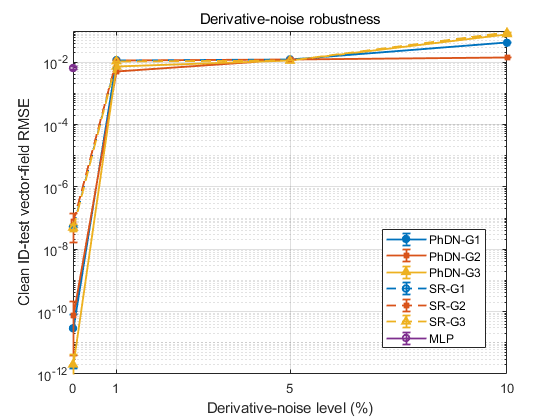

noiseRows = systemIdentificationRows;
if ~isempty(noiseRows) && isfield(noiseRows,'method')
    keepPrimary = ismember(lower(string({noiseRows.method})), ...
        lower(string(RobustnessComparisonMethods)));
    noiseRows = noiseRows(keepPrimary);
end
if ~isempty(noiseRows)
    methodRank = zeros(1,numel(noiseRows));
    for iRowSort = 1:numel(noiseRows)
        rankCandidate = find(strcmpi(RobustnessComparisonMethods,noiseRows(iRowSort).method),1);
        if isempty(rankCandidate); rankCandidate = numel(RobustnessComparisonMethods)+1; end
        methodRank(iRowSort) = rankCandidate;
    end
    [~,rowOrder] = sortrows([[noiseRows.roundIndex].',[noiseRows.noiseLevel].',methodRank.'],[1 2 3]);
    noiseRows = noiseRows(rowOrder);
end

detailedTable = soft_saturated_lorenz96_noise_rows_to_table(noiseRows);
detailedCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_all_runs.csv');
writetable(detailedTable,detailedCsvPath);
[figNoise,noiseFigureData,noiseSummaryTable] = ...
    plot_soft_saturated_lorenz96_noise_robustness( ...
        noiseRows,'Visible',true,'YLimits',RMSEFigureYLimits);
summaryCsvPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_mean_std.csv');
writetable(noiseSummaryTable,summaryCsvPath);
figureDataPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness_figure_data.mat');
save(figureDataPath,'noiseFigureData','noiseSummaryTable','-v7.3');
figPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness.fig');
pdfPath = fullfile(OutputSummaryDir,'lorenz96_noise_robustness.pdf');
savefig(figNoise,figPath);
try
    exportgraphics(figNoise,pdfPath,'ContentType','vector');
catch
    set(figNoise,'PaperPositionMode','auto');
    print(figNoise,pdfPath,'-dpdf','-painters');
end


protocol = struct();
protocol.system = caseDefinitionTask.name;
protocol.prior = 'G1_G2_G3';
protocol.comparisonMethods = RobustnessComparisonMethods;
protocol.includeStage0SRAblationsInComparison = IncludeStage0SRAblationsInComparison;
protocol.incrementalMergeEnabled = true;
protocol.nTrain = TrainingSampleList;
protocol.noiseLevels = NoiseLevels;
protocol.numRounds = NumRounds;
protocol.noiseFormula = 'Y_tilde(:,j)=Y(:,j)+rho*std(Ytrain_clean(:,j))*epsilon(:,j)';
protocol.trainValidationNoisy = true;
protocol.idTestClean = true;
protocol.oodEnabled = false;
protocol.rolloutEnabled = false;
protocol.fixedStateSamplesAcrossRounds = true;
protocol.pairedNoiseRealizationAcrossRhoWithinRound = true;
protocol.baseNoiseSeed = BaseNoiseSeed;
protocol.stage0BypassThreshold = Stage0SingleLayerBypassThreshold;
protocol.stage0TotalPopulations = Stage0InnerPopulations;
protocol.primaryMetric = 'clean_id_test_vector_field_rmse';
protocol.completeCaseWallTime = completeCaseWallTime;
save(ResultsFile,'allResults','noiseRows','noiseSummaryTable','protocol','-v7.3');

fprintf('Lorenz--96 noise robustness outputs saved under:\n%s\n',OutputCaseRoot);

Lorenz--96 noise robustness outputs saved under:
D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness


fprintf('Aggregate MAT: %s\n',ResultsFile);

Aggregate MAT: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\soft_saturated_lorenz96_noise_robustness_results.mat


fprintf('Detailed CSV : %s\n',detailedCsvPath);

Detailed CSV : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\lorenz96_noise_robustness_all_runs.csv


fprintf('Mean/std CSV : %s\n',summaryCsvPath);

Mean/std CSV : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\lorenz96_noise_robustness_mean_std.csv


fprintf('Paper PDF    : %s\n',pdfPath);

Paper PDF    : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SoftSaturatedLorenz96_K10_F8_kappa1_NoiseRobustness\summary\lorenz96_noise_robustness.pdf
